# Tutorial: Using CruiseViz for taking a first and fast look at CTD transects at sea

(with focus on transects in regions with complicated bathymetry such as fjords)

clc; close all; clear;
load('data/bathymetry_johanpeterson_bedm6.mat'); % Load bathymetry

**Note: **

- To use CruiseViz without dependency problems, add entire folder (incl. subfolders) under "Home >> Set Path". 

- Execute Tutorial in same folder where it is saved. 

## A] Set up data file

CruiseViz processing and plotting functions expect CTD profiles to be provided as a MATLAB structure with the data vectors/arrays in the following format (here, the structure 'ctd' contains M CTD profiles on an identical pressure grid with Z pressure levels):

- `ctd.station` (1xM) = Vector with profile information (e.g., name, latitude)

- `ctd.pres`       (Zx1)  = Pressure vector (identical for all variables)

- `ctd.vari `     (ZxM) = variable arrays (e.g., temperature, salinity)

The following functions aim to support the user in creating 'ctd':

### *i] From SBE ascii-files (.cnv) of downcast to CruiseViz Matlab structure *`ctd`*:*

*Use function *`cv_read_cnv2struct.m`*. The user needs to provide information about a) which variables should get read and b) where to find them within the ascii-file:*

path_load      = 'data/ctd_cnv_files';
clear variab;
variab.filename = 'dmsm130_*'; % first digit of station number in file
variab.write    = {'temp','sali','oxy','turb','fluor'}; % Variables of interest
variab.loc      = [3 18 17 10 5]; % column number of variables
variab.loc_pres = 8;   % Location of pressure vector in data table

ctd = cv_read_cnv2struct(path_load,variab);
save('data/ctd_sermilik2024_ready2plot.mat','ctd');

The result looks like this: 

ctd

ctd = struct with fields:
            nb: [1 2 3 4 5 6 7 8]
       station: {'010'  '011'  '012'  '013'  '022a'  '023'  '024'  '025'}
          time: [7.3945e+05 7.3945e+05 7.3945e+05 7.3945e+05 7.3945e+05 7.3945e+05 7.3945e+05 7.3945e+05]
           lon: [-43.3393 -43.4477 -43.5547 -43.6907 -43.6278 -43.6707 -43.6902 -43.7230]
           lat: [60.4643 60.4878 60.5082 60.5282 60.5858 60.6255 60.6940 60.7137]
          pres: [872×1 double]
          temp: [872×8 double]
          sali: [872×8 double]
           oxy: [872×8 double]
          turb: [872×8 double]
         fluor: [872×8 double]
          salt: [872×8 double]
        theta0: [872×8 double]
          dens: [872×8 double]
    sigmatheta: [872×8 double]
         depth: [872×8 double]
      pres_max: [780 825 872 718 471 426 349 176]


### *ii] From Matlab structure of individual profiles to 'ctd':*

*If your data is currently in a format like this:*

data_input = load('data/ctd_struct_raw_isertupkangertiva2024.mat');
data_input.CTDstruct

ans = struct with fields:
        lat: [65.7215 65.7099 65.6994 65.6916 65.6630 65.6518 65.6416 65.6370 65.6121 65.5899 65.5708 65.4850]
        lon: [-39.2486 -39.2499 -39.2323 -39.2114 -39.1756 -39.1711 -39.1623 -39.1387 -39.1064 -39.0790 -39.0510 -39.0496]
       time: [7.3948e+05 7.3948e+05 7.3948e+05 7.3948e+05 7.3948e+05 7.3948e+05 7.3948e+05 7.3948e+05 7.3948e+05 7.3948e+05 7.3948e+05 7.3947e+05]
    station: {'05'  '06'  '07'  '08'  '09'  '10'  '11'  '12'  '13b'  '14'  '15'  '151'}
        pre: {[5146×1 double]  [6152×1 double]  [6865×1 double]  [6902×1 double]  [4661×1 double]  [3508×1 double]  [4793×1 double]  [4736×1 double]  [3667×1 double]  [2672×1 double]  [4491×1 double]  [327×1 double]}
        tem: {[5146×1 double]  [6152×1 double]  [6865×1 double]  [6902×1 double]  [4661×1 double]  [3508×1 double]  [4793×1 double]  [4736×1 double]  [3667×1 double]  [2672×1 double]  [4491×1 double]  [327×1 double]}
        sal: {[5146×1 double]  [6152×1 double]  [6865×1 double]  [6902×

Use 'read_struct2struct.m':

variab_read  = {'station','lon','lat','time','tem' ,'sal' ,'turb'};
variab_write = {'station','lon','lat','time','temp','sali','turb'};
variab_pres  = {'pre'};
ctd = cv_read_struct2struct(data_input,variab_read,variab_write,variab_pres);
save('data/ctd_isertupkangertiva2024_ready2plot.mat','ctd');

The functions above call a subset of functions from the TEOS-10 GSW-toolbox (https://www.teos-10.org/software.htm; also saved in folder 'gsw_teos10') to derive variables of interest. The following GSW-functions can as well be called directly:

% Absolute Salinity
ctd.salt       = gsw_SA_from_SP(ctd.sali,ctd.pres,ctd.lon,ctd.lat); % Absolute salinity [g/kg]
% Thermodynamics
ctd.theta0     = gsw_pt_from_t(ctd.salt,ctd.temp,ctd.pres,0); % Potential temperture [degC]
ctd.Theta0     = gsw_CT_from_t(ctd.salt,ctd.temp,ctd.pres); % Conservative temperature [degC]
ctd.sigmatheta = gsw_pot_rho_t_exact(ctd.salt,ctd.temp,ctd.pres,0) - 1000; % Reduced potential density [kg/m3]
ctd.cp         = gsw_cp_t_exact(ctd.salt,ctd.temp,ctd.pres); % Heat capacity [J/kg/K]
ctd.alpha      = gsw_alpha_wrt_t_exact(ctd.salt,ctd.temp,ctd.pres); % Thermal expansion coefficient [1/K]
ctd.beta       = gsw_beta_const_t_exact(ctd.salt,ctd.temp,ctd.pres); % Haline contraction coefficient [kg/g]
ctd.c          = gsw_sound_speed(ctd.salt,ctd.Theta0,ctd.pres); % Sound speed [m/s]
% Ocean depth level (as alternative to pressure level
ctd.z          = -gsw_z_from_p(repmat(ctd.pres,1,length(ctd.lat)),ctd.lat); % Ocean depth level [m]

## B] Plot a transect

Load Matlab structure 'ctd' with CTD profiles:

load('data/ctd_johanpeterson2025_ready2plot.mat');

Select transect of interest:

station_str = {'11','09','10a','08','07'}; % List of station names in order of transect
ind = cv_station2ind(ctd.station,station_str);

### ***i] Create interpolated transect:***

flag_connect = 0; % Bathymetry-guided transect
variab       = {'theta0','salt','sigmatheta','oxy'}; % list of variable names to be interpolated
                                                     % (for part c ('plot_transect_collage.m'), list needs to contain 
                                                     %  at least four fields, incl. 'theta0', 'salt', 'sigmatheta', 
                                                     %  and one additional variable of interest; here: 'oxy')
flag_extrap  = 1; % bathymetry-restricted interpolation in basins

trans = cv_design_transect(ctd,station_str,flag_connect,variab,bathy,flag_extrap);

### ***ii] Plot transect of an individual variable***

Mandatory inputs from Matlab structure `trans` (output of `cv_design_transsect.m`)

- Transect distance vector (`dist`)

- pressure level vector (`pres`)

- 2D array containing variable of interest.  

All other inputs (i.e., density field for contours, bathymetry/ocean depth along transect, location and names of CTD stations, ...) are optional. However, 'design_transect.m' typically provides these fields. 

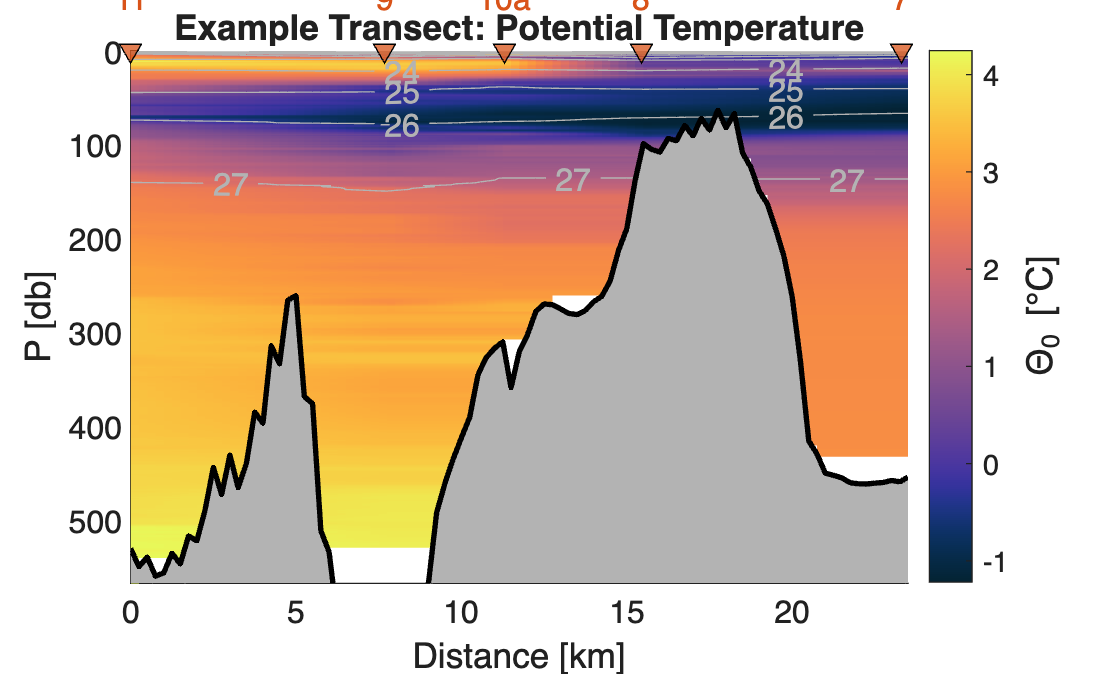

close(figure(1)); figure(1)
title_str = 'Example Transect: Potential Temperature';
col.map   = 'thermal'; col.str_vari = '\Theta_0 [°C]';
cv_plot_transect(trans.dist,trans.pres,trans.theta0,trans.sigmatheta,...
                 trans.depth,[],trans.ctd.dist,trans.ctd.station,title_str,'Distance [km]',col);

### ***iii] Plot transect collage/ensemble *****(THE FASTEST PATH TOWARD A QUICK LOOK AT SEA)**

... consisting of transects of temperature, salinity, and an additional variable of choice, as well as a T/S-plot, and station map. The function `cv_plot_transect_collage.m` is optimized for the output 'trans' from 'design_transect.m':

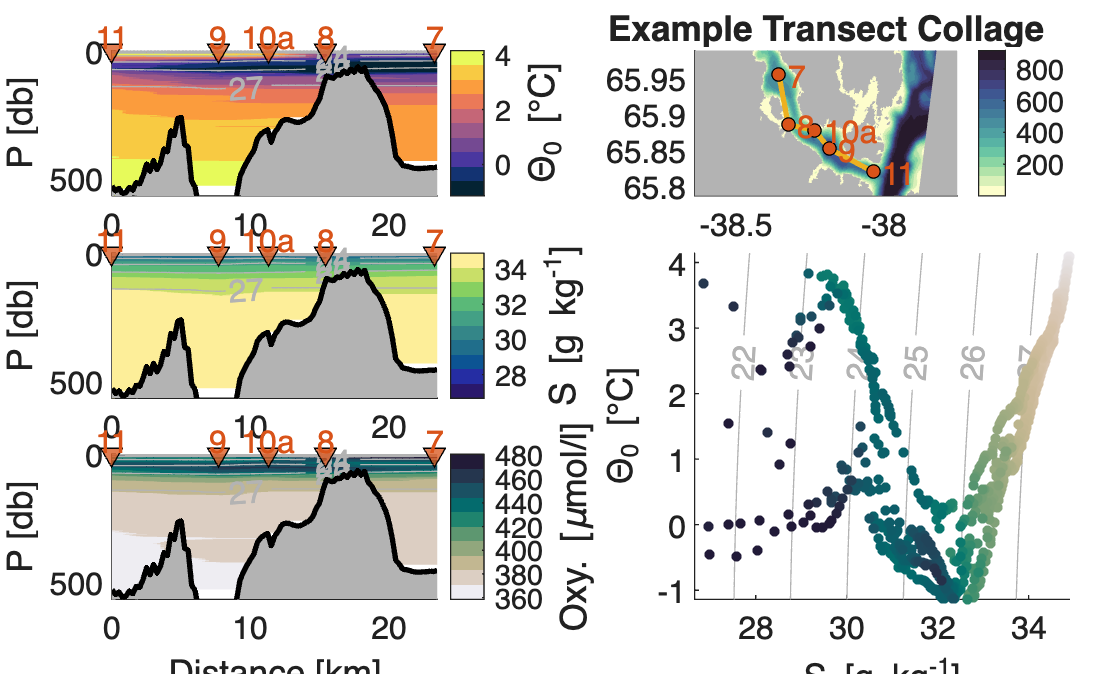

close(figure(2)); figure(2)
str_title = 'Example Transect Collage';
str_vari.short = 'oxy'; str_vari.long = 'Oxy. [\mumol/l]'; % Additional variable name
cv_plot_transect_collage(trans,str_title,str_vari,bathy)

## C] Exploring User Flags

In the following examples, **user-flags **are being varied to visualize how CruiseViz can be applied for different purposes. Most adaptations can be made when creating the interpolated transect with `cv_design_transect.m`

### *i] Vary transect path between CTD stations*

*In the example above, the chosen transect path is guided by bathymetry. Here, we compare three options to connect transects:*

- *Bathymetry-guidance between all CTD stations*

- *Directly-connected CTD stations following the great-circle-path*

- Bathymetry-guidance only for designated segments of the transect

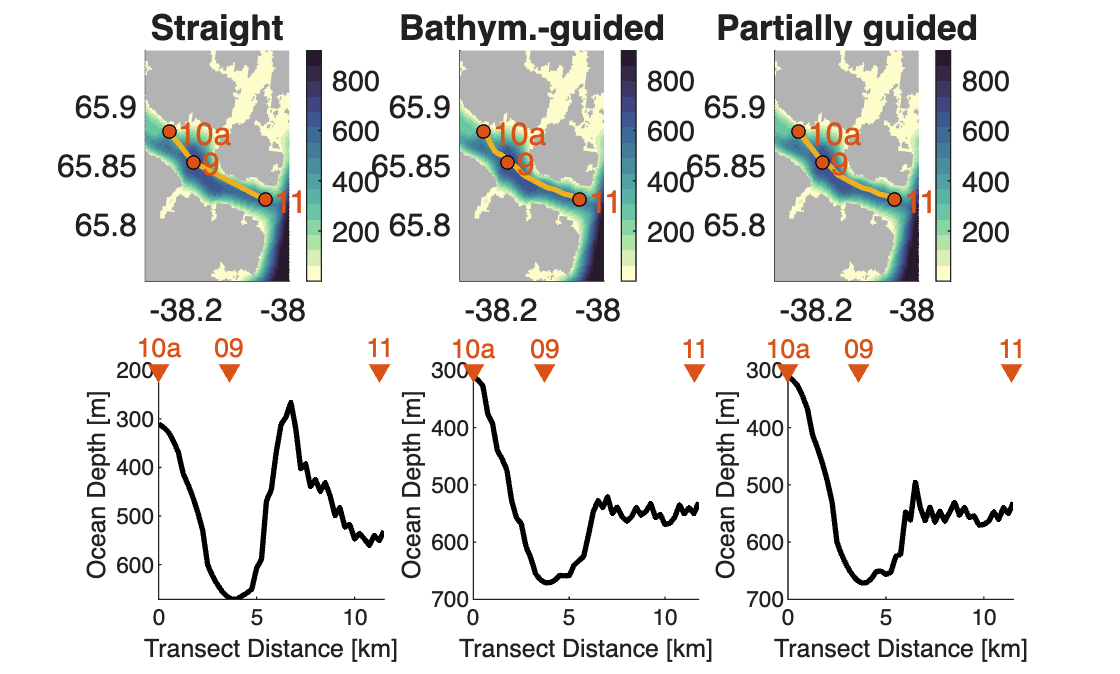

station_str = {'10a','09','11'};

close(figure(3)); figure(3);
for j=1:3
    if j==1 
        flag_connect = 0; % Directly-connected CTD stations 
        title_str = 'Straight';
    elseif j==2
        flag_connect = 1; % Bathymetry-guided connections
        title_str = 'Bathym.-guided';
    else
        flag_connect = [0 1]; % Bathymetry-guidance only for last segment (between two last stations)
                              % (instead of boolean, provide array of booleans to
                              %  set parameter for each segment individually)
        title_str = 'Partially guided';
    end

    trans = cv_design_transect(ctd,station_str,flag_connect,variab,bathy,flag_extrap);
    
    subplot(2,3,j); hold on 
    cv_plot_map(trans,title_str,bathy);
    subplot(2,3,3+j); hold on
    plot(trans.dist,trans.depth,'k','Linewidth',2); yL = ylim;
    scatter(trans.ctd.dist,yL(1),50,'v','filled','MarkerFaceColor',[0.8500 0.3250 0.0980]);
    text(trans.ctd.dist,(yL(1)-(yL(2)-yL(1))/10)*ones(size(trans.ctd.station)),trans.ctd.station,'Color',[0.8500 0.3250 0.0980],'HorizontalAlignment','center')
    set(gca,'ydir','reverse'); xlabel('Transect Distance [km]'); ylabel('Ocean Depth [m]')
end

While the directly-connected transect (**left panel**) suggests that stations `09` and `11` are separated by a shallow sill (at roughly distance = 7 km), the bathymetry-guided transect (**center panel**) better follows the channel and visualizes the connectedness between neighboring stations, not separated by bathymetry. 

However, curving the transect path is i) more computationally intensive (due to a gradient descent algorithm used to modulate transect path) and ii) not necessary between all stations. Thus, rather than applying `flag_connect=1` for the entire transect, switch on bathymetry-guidance for segments where it makes sense (e.g., corners in the fjord), i.e., only between stations `09` and `11` (**right panel**).

#### **Vary tuning parameters for bathymetry-guidance**

In addition, users can vary tuning parameters, saved in the Matlab structure 'param_connect' (see `cv_bathymetry_guided_connector.m` for more details). 

Here, we vary the parameter `alpha`, which regulates how straight the connector between stations is supposed to be vs. how much the path is supposed to be guided by bathymetry: 

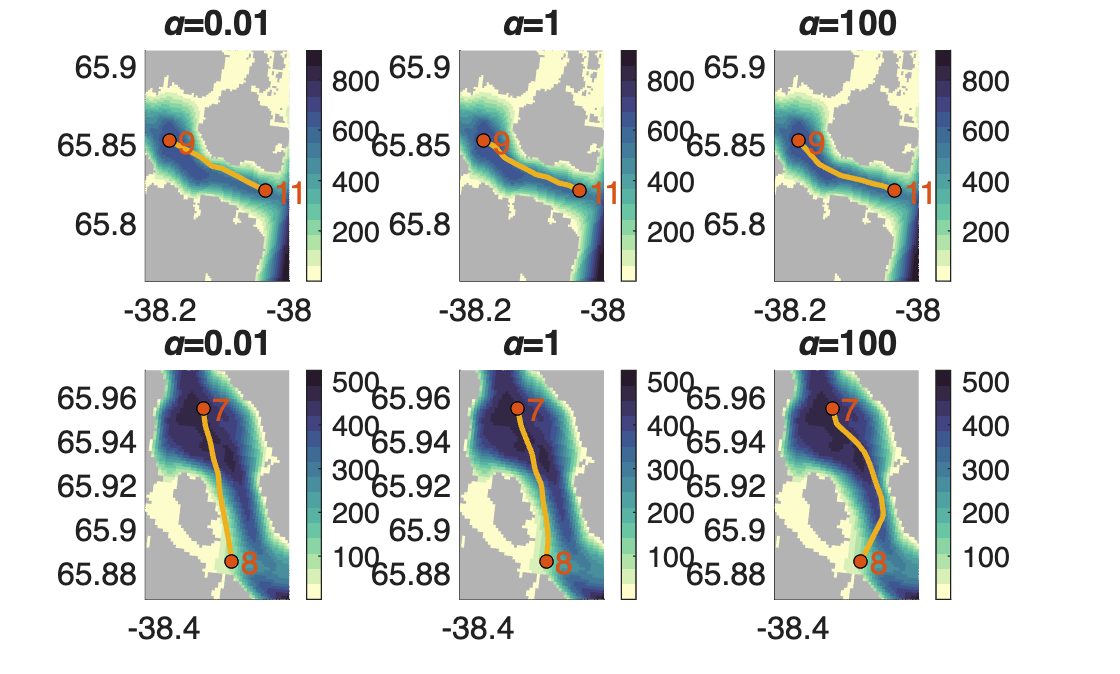

alpha = 10.^(-2:2:2);
station_strA = {'09','11'}; 
station_strB = {'08','07'};
flag_connect = 1;

N = length(alpha);
close(figure(4)); figure(4);
for j=1:N
    clear param_connect; param_connect.alpha = alpha(j);

    % Connector between '09' and '11'
    trans = cv_design_transect(ctd,station_strA,flag_connect,variab,bathy,flag_extrap,[],[],param_connect);
    subplot(2,N,j); hold on
    cv_plot_map(trans,strcat("\alpha=",num2str(alpha(j))),bathy);

    % Connector between '07' and '08'
    trans = cv_design_transect(ctd,station_strB,flag_connect,variab,bathy,flag_extrap,[],[],param_connect);
    subplot(2,N,j+N); hold on
    cv_plot_map(trans,strcat("\alpha=",num2str(alpha(j))),bathy);
end

### *ii] Turn on/off bathymetry-restricted extrapolation*

*Bathymetry-restricted extrapolation allows to fill basins with data from a nearby CTD station by assuming homogeneity; extrapolation never crosses bathymetry along the transect*

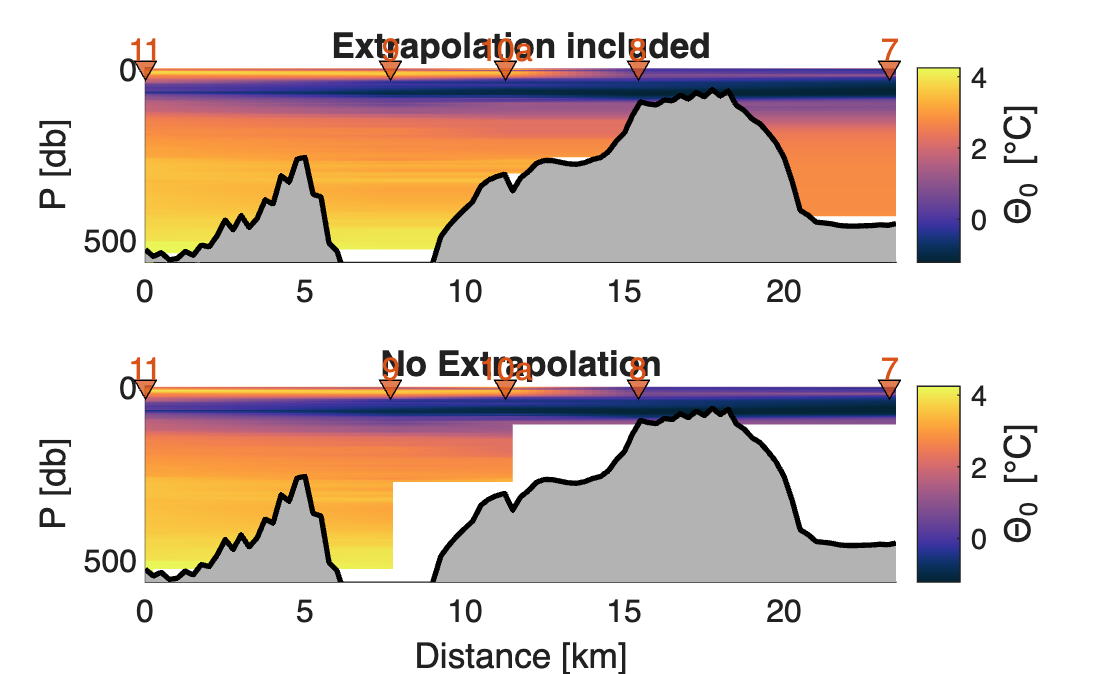

station_str = {'11','09','10a','08','07'}; % List of station names in transect

close(figure(5)); figure(5)
% Extrapolation included:
flag_connect = 0; % Directly-connected CTD stations
flag_extrap  = 1; % Turn on extrapolation
trans4 = cv_design_transect(ctd,station_str,flag_connect,'theta0',bathy,flag_extrap);

subplot(2,1,1);
title_str = 'Extrapolation included';
col.map   = 'thermal'; col.str_vari = '\Theta_0 [°C]';
cv_plot_transect(trans4.dist,trans4.pres,trans4.theta0,[],...
                 trans4.depth,[],trans4.ctd.dist,trans4.ctd.station,title_str,[],col);
cL = clim;

% No extrapolation:
flag_connect = 0;
flag_extrap  = 0; % Turn off extrapolation
trans5 = cv_design_transect(ctd,station_str,flag_connect,'theta0',bathy,flag_extrap);

subplot(2,1,2)
title_str = 'No Extrapolation';
cv_plot_transect(trans5.dist,trans5.pres,trans5.theta0,[],...
                 trans5.depth,[],trans5.ctd.dist,trans5.ctd.station,title_str,'Distance [km]',col);
clim(cL)